prefix = 'global'

prefix = 'global'

eval(['load_data_' prefix]);


maxt = size(data_4, 2);
goback = 56

goback = 56

thisday = maxt - goback;
forecast_date = datetime(2020, 1, 23)+caldays(thisday);
path = '../results/historical_forecasts/';
dirname = datestr(forecast_date, 'yyyy-mm-dd');
fullpath = [path dirname];

ftab = readtable([fullpath '/' prefix '_forecasts_cases.csv']);
dtab = readtable([fullpath '/' prefix '_forecasts_deaths.csv']);
cnames = ftab{2:end, 2};
infec_pred = ftab{2:end, 3:end};
death_pred = dtab{2:end, 3:end};


figure('DefaultAxesFontSize',18);
sel_reg = "US"; % Select a region to predict
un = 20;
sel_horizon = 75

sel_horizon = 75

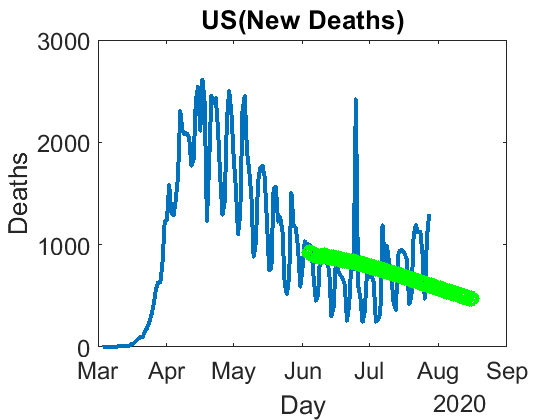

 

xx = find(startsWith(countries, sel_reg));
if isempty(xx)
    cid = 1; % Default to the first region in the list
else
    cid = xx(1);
end

offset = 40;
trueshow = (offset:maxt);
Tx = datetime(2020, 1, 23)+ caldays(trueshow-1);
plot(Tx(2:end), diff(deaths(cid, trueshow)), 'LineWidth', 3);
hold on;

Tx = forecast_date + caldays(0:sel_horizon-1);
yy = diff(death_pred(cid, 1:sel_horizon));
yy = (yy); Tx = Tx(2:end);
plot(Tx, yy, 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10);
hold off;

title([countries{cid} '(New Deaths)'])
xlabel('Day');
ylabel('Deaths');

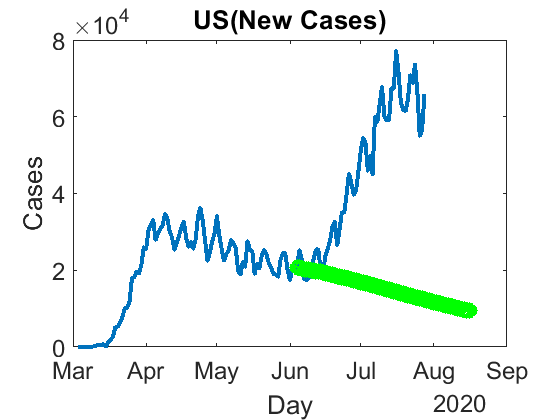


Tx = datetime(2020, 1, 23)+ caldays(trueshow-1);
plot(Tx(2:end), diff(data_4(cid, trueshow)), 'LineWidth', 3);
hold on;

Tx = forecast_date + caldays(0:sel_horizon-1);
yy = infec_pred(cid, 1:sel_horizon);
yy = diff(yy); Tx = Tx(2:end);
plot(Tx, yy, 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10);
hold off;

title([countries{cid} '(New Cases)'])
xlabel('Day');
ylabel('Cases');